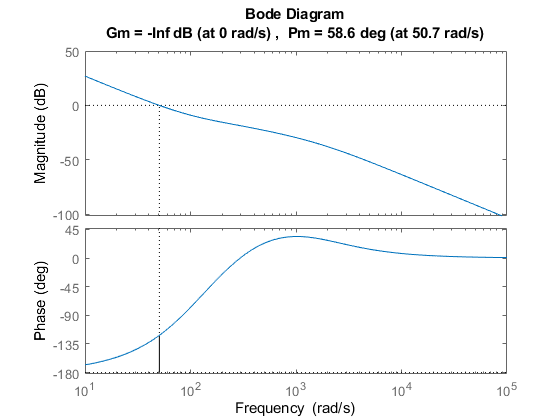

mech.L = 0.5;
mech.l = 0.1;
mech.h = 0.5;
mech.H = 0.3;
mech.L = 1;
mech.hp = 0.2;
mech.mud = 0.000002;

const.g = 9.81;

stepper.La = 10e-3;
stepper.Ra = 15;
stepper.Kg = 0.1;
stepper.Km = 0.2;
stepper.tausf = 10e-9;
stepper.Jeq = 10e-6;
stepper.Beq = 10e-7;
stepper.p = 2;

% requests
request.Mp = 0.1;
request.ts = 0.1;
request.alpha = 4;

s = tf('s');
T = -const.g*mech.l/mech.L*1/(s*s);
M = stepper.Km*s/(s*s*stepper.Jeq*stepper.La+s*(stepper.Jeq*stepper.Ra+stepper.Beq*stepper.La)+stepper.Beq*stepper.Ra-stepper.Km*stepper.Km);
P = M*T;

[request.wc, request.phm] = getWgcPhim(request.Mp, request.ts);
request.fc = request.wc/2/pi;
[pid.Kp, pid.Ki, pid.Kd] = getPIDBodeFreq(P, request.fc, request.phm, request.alpha);
pid.T_l = 1/(10*request.wc);
pid.Kw  = 5/request.ts;

C = pid.Kp + pid.Ki/s + pid.Kd*s;
margin(C*P)

%% Definition of Bode Method
% set of utility routines

function [wgc, phim] = getWgcPhim(Mp, ts)
    delta = log(1/Mp)/sqrt(pi^2+log(1/Mp)^2);
    wgc = 3/delta/ts;
    phim = 180/pi*atan(2*delta/sqrt(sqrt(1+4*delta^4)-2*delta^2)); % Phase margin [deg]
end

function [Kp,Ki,Kd] = getPIDBodeFreq(plant, freq, phim, alpha)
    wgc = 2*pi*freq;
    [Kp,Ki,Kd] = getPIDBode(plant, wgc, phim, alpha);
end

function [Kp,Ki,Kd] = getPIDBode(plant, wgc, phim, alpha)
    [mag, phase] = bode(plant, wgc);
    DeltaK = 1 / mag;
    DeltaPhi = -180 + phim - phase;
    tmp = tand(DeltaPhi);
    Td = (tmp + sqrt(tmp^2 + 4/alpha))/(2*wgc);
    Ti = alpha * Td;
    Kp = DeltaK * cosd(DeltaPhi);
    Ki = Kp / Ti;
    Kd = Kp * Td;
    s = tf('s');
    C = Kp + Ki * 1/s + Kd * s;
    %[a,b,c,d] = margin(C*plant);
    %delta_wgc = c - wgc;
    %delta_phim = d - phim;
    %assert(delta_wgc < 0.01, "failed to build PID");
    %assert(delta_phim < 0.01, "failed to build PID");
end